# Create BAC Classifier ResNet-22 Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 16-Mar-2023 08:28:10

## Load the Pretrained Parameters

params = load("params_2023_03_16__08_27_59.mat");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([1230 997 1],"Name","image_input.1","Normalization","none")
    convolution2dLayer([7 7],16,"Name","Conv_0","Stride",[2 2],"Bias",params.Conv_0.Bias,"Weights",params.Conv_0.Weights)
    maxPooling2dLayer([3 3],"Name","MaxPool_1","Stride",[2 2])
    batchNormalizationLayer("Name","BatchNormalization_2","Offset",params.BatchNormalization_2.Offset,"Scale",params.BatchNormalization_2.Scale,"TrainedMean",params.BatchNormalization_2.TrainedMean,"TrainedVariance",params.BatchNormalization_2.TrainedVariance)
    reluLayer("Name","Relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],16,"Name","Conv_5","Padding",[1 1 1 1],"Bias",params.Conv_5.Bias,"Weights",params.Conv_5.Weights)
    batchNormalizationLayer("Name","BatchNormalization_6","Offset",params.BatchNormalization_6.Offset,"Scale",params.BatchNormalization_6.Scale,"TrainedMean",params.BatchNormalization_6.TrainedMean,"TrainedVariance",params.BatchNormalization_6.TrainedVariance)
    reluLayer("Name","Relu_7")
    convolution2dLayer([3 3],16,"Name","Conv_8","Padding",[1 1 1 1],"Bias",params.Conv_8.Bias,"Weights",params.Conv_8.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([1 1],16,"Name","Conv_4","Bias",params.Conv_4.Bias,"Weights",params.Conv_4.Weights);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","Add_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","BatchNormalization_10","Offset",params.BatchNormalization_10.Offset,"Scale",params.BatchNormalization_10.Scale,"TrainedMean",params.BatchNormalization_10.TrainedMean,"TrainedVariance",params.BatchNormalization_10.TrainedVariance)
    reluLayer("Name","Relu_11")
    convolution2dLayer([3 3],16,"Name","Conv_12","Padding",[1 1 1 1],"Bias",params.Conv_12.Bias,"Weights",params.Conv_12.Weights)
    batchNormalizationLayer("Name","BatchNormalization_13","Offset",params.BatchNormalization_13.Offset,"Scale",params.BatchNormalization_13.Scale,"TrainedMean",params.BatchNormalization_13.TrainedMean,"TrainedVariance",params.BatchNormalization_13.TrainedVariance)
    reluLayer("Name","Relu_14")
    convolution2dLayer([3 3],16,"Name","Conv_15","Padding",[1 1 1 1],"Bias",params.Conv_15.Bias,"Weights",params.Conv_15.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","Add_16")
    batchNormalizationLayer("Name","BatchNormalization_17","Offset",params.BatchNormalization_17.Offset,"Scale",params.BatchNormalization_17.Scale,"TrainedMean",params.BatchNormalization_17.TrainedMean,"TrainedVariance",params.BatchNormalization_17.TrainedVariance)
    reluLayer("Name","Relu_18")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","Conv_20","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.Conv_20.Bias,"Weights",params.Conv_20.Weights)
    batchNormalizationLayer("Name","BatchNormalization_21","Offset",params.BatchNormalization_21.Offset,"Scale",params.BatchNormalization_21.Scale,"TrainedMean",params.BatchNormalization_21.TrainedMean,"TrainedVariance",params.BatchNormalization_21.TrainedVariance)
    reluLayer("Name","Relu_22")
    convolution2dLayer([3 3],32,"Name","Conv_23","Padding",[1 1 1 1],"Bias",params.Conv_23.Bias,"Weights",params.Conv_23.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([1 1],32,"Name","Conv_19","Stride",[2 2],"Bias",params.Conv_19.Bias,"Weights",params.Conv_19.Weights);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","Add_24");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","BatchNormalization_25","Offset",params.BatchNormalization_25.Offset,"Scale",params.BatchNormalization_25.Scale,"TrainedMean",params.BatchNormalization_25.TrainedMean,"TrainedVariance",params.BatchNormalization_25.TrainedVariance)
    reluLayer("Name","Relu_26")
    convolution2dLayer([3 3],32,"Name","Conv_27","Padding",[1 1 1 1],"Bias",params.Conv_27.Bias,"Weights",params.Conv_27.Weights)
    batchNormalizationLayer("Name","BatchNormalization_28","Offset",params.BatchNormalization_28.Offset,"Scale",params.BatchNormalization_28.Scale,"TrainedMean",params.BatchNormalization_28.TrainedMean,"TrainedVariance",params.BatchNormalization_28.TrainedVariance)
    reluLayer("Name","Relu_29")
    convolution2dLayer([3 3],32,"Name","Conv_30","Padding",[1 1 1 1],"Bias",params.Conv_30.Bias,"Weights",params.Conv_30.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","Add_31")
    batchNormalizationLayer("Name","BatchNormalization_32","Offset",params.BatchNormalization_32.Offset,"Scale",params.BatchNormalization_32.Scale,"TrainedMean",params.BatchNormalization_32.TrainedMean,"TrainedVariance",params.BatchNormalization_32.TrainedVariance)
    reluLayer("Name","Relu_33")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([1 1],64,"Name","Conv_34","Stride",[2 2],"Bias",params.Conv_34.Bias,"Weights",params.Conv_34.Weights);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","Conv_35","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.Conv_35.Bias,"Weights",params.Conv_35.Weights)
    batchNormalizationLayer("Name","BatchNormalization_36","Offset",params.BatchNormalization_36.Offset,"Scale",params.BatchNormalization_36.Scale,"TrainedMean",params.BatchNormalization_36.TrainedMean,"TrainedVariance",params.BatchNormalization_36.TrainedVariance)
    reluLayer("Name","Relu_37")
    convolution2dLayer([3 3],64,"Name","Conv_38","Padding",[1 1 1 1],"Bias",params.Conv_38.Bias,"Weights",params.Conv_38.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","Add_39");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","BatchNormalization_40","Offset",params.BatchNormalization_40.Offset,"Scale",params.BatchNormalization_40.Scale,"TrainedMean",params.BatchNormalization_40.TrainedMean,"TrainedVariance",params.BatchNormalization_40.TrainedVariance)
    reluLayer("Name","Relu_41")
    convolution2dLayer([3 3],64,"Name","Conv_42","Padding",[1 1 1 1],"Bias",params.Conv_42.Bias,"Weights",params.Conv_42.Weights)
    batchNormalizationLayer("Name","BatchNormalization_43","Offset",params.BatchNormalization_43.Offset,"Scale",params.BatchNormalization_43.Scale,"TrainedMean",params.BatchNormalization_43.TrainedMean,"TrainedVariance",params.BatchNormalization_43.TrainedVariance)
    reluLayer("Name","Relu_44")
    convolution2dLayer([3 3],64,"Name","Conv_45","Padding",[1 1 1 1],"Bias",params.Conv_45.Bias,"Weights",params.Conv_45.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","Add_46")
    batchNormalizationLayer("Name","BatchNormalization_47","Offset",params.BatchNormalization_47.Offset,"Scale",params.BatchNormalization_47.Scale,"TrainedMean",params.BatchNormalization_47.TrainedMean,"TrainedVariance",params.BatchNormalization_47.TrainedVariance)
    reluLayer("Name","Relu_48")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","Conv_50","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.Conv_50.Bias,"Weights",params.Conv_50.Weights)
    batchNormalizationLayer("Name","BatchNormalization_51","Offset",params.BatchNormalization_51.Offset,"Scale",params.BatchNormalization_51.Scale,"TrainedMean",params.BatchNormalization_51.TrainedMean,"TrainedVariance",params.BatchNormalization_51.TrainedVariance)
    reluLayer("Name","Relu_52")
    convolution2dLayer([3 3],128,"Name","Conv_53","Padding",[1 1 1 1],"Bias",params.Conv_53.Bias,"Weights",params.Conv_53.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([1 1],128,"Name","Conv_49","Stride",[2 2],"Bias",params.Conv_49.Bias,"Weights",params.Conv_49.Weights);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","Add_54");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","BatchNormalization_55","Offset",params.BatchNormalization_55.Offset,"Scale",params.BatchNormalization_55.Scale,"TrainedMean",params.BatchNormalization_55.TrainedMean,"TrainedVariance",params.BatchNormalization_55.TrainedVariance)
    reluLayer("Name","Relu_56")
    convolution2dLayer([3 3],128,"Name","Conv_57","Padding",[1 1 1 1],"Bias",params.Conv_57.Bias,"Weights",params.Conv_57.Weights)
    batchNormalizationLayer("Name","BatchNormalization_58","Offset",params.BatchNormalization_58.Offset,"Scale",params.BatchNormalization_58.Scale,"TrainedMean",params.BatchNormalization_58.TrainedMean,"TrainedVariance",params.BatchNormalization_58.TrainedVariance)
    reluLayer("Name","Relu_59")
    convolution2dLayer([3 3],128,"Name","Conv_60","Padding",[1 1 1 1],"Bias",params.Conv_60.Bias,"Weights",params.Conv_60.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","Add_61")
    batchNormalizationLayer("Name","BatchNormalization_62","Offset",params.BatchNormalization_62.Offset,"Scale",params.BatchNormalization_62.Scale,"TrainedMean",params.BatchNormalization_62.TrainedMean,"TrainedVariance",params.BatchNormalization_62.TrainedVariance)
    reluLayer("Name","Relu_63")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([1 1],256,"Name","Conv_64","Stride",[2 2],"Bias",params.Conv_64.Bias,"Weights",params.Conv_64.Weights);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","Conv_65","Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.Conv_65.Bias,"Weights",params.Conv_65.Weights)
    batchNormalizationLayer("Name","BatchNormalization_66","Offset",params.BatchNormalization_66.Offset,"Scale",params.BatchNormalization_66.Scale,"TrainedMean",params.BatchNormalization_66.TrainedMean,"TrainedVariance",params.BatchNormalization_66.TrainedVariance)
    reluLayer("Name","Relu_67")
    convolution2dLayer([3 3],256,"Name","Conv_68","Padding",[1 1 1 1],"Bias",params.Conv_68.Bias,"Weights",params.Conv_68.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","Add_69");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","BatchNormalization_70","Offset",params.BatchNormalization_70.Offset,"Scale",params.BatchNormalization_70.Scale,"TrainedMean",params.BatchNormalization_70.TrainedMean,"TrainedVariance",params.BatchNormalization_70.TrainedVariance)
    reluLayer("Name","Relu_71")
    convolution2dLayer([3 3],256,"Name","Conv_72","Padding",[1 1 1 1],"Bias",params.Conv_72.Bias,"Weights",params.Conv_72.Weights)
    batchNormalizationLayer("Name","BatchNormalization_73","Offset",params.BatchNormalization_73.Offset,"Scale",params.BatchNormalization_73.Scale,"TrainedMean",params.BatchNormalization_73.TrainedMean,"TrainedVariance",params.BatchNormalization_73.TrainedVariance)
    reluLayer("Name","Relu_74")
    convolution2dLayer([3 3],256,"Name","Conv_75","Padding",[1 1 1 1],"Bias",params.Conv_75.Bias,"Weights",params.Conv_75.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","Add_76")
    batchNormalizationLayer("Name","BatchNormalization_77","Offset",params.BatchNormalization_77.Offset,"Scale",params.BatchNormalization_77.Scale,"TrainedMean",params.BatchNormalization_77.TrainedMean,"TrainedVariance",params.BatchNormalization_77.TrainedVariance)
    reluLayer("Name","Relu_78")
    averagePooling2dLayer([5 5],"Name","avgpool2d","Padding","same")
    dropoutLayer(0.5,"Name","dropout_1")
    fullyConnectedLayer(256,"Name","fc_1")
    dropoutLayer(0.5,"Name","dropout_2")
    fullyConnectedLayer(2,"Name","fc_2")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"Relu_3","Conv_5");
lgraph = connectLayers(lgraph,"Relu_3","Conv_4");
lgraph = connectLayers(lgraph,"Conv_8","Add_9/in1");
lgraph = connectLayers(lgraph,"Conv_4","Add_9/in2");
lgraph = connectLayers(lgraph,"Add_9","BatchNormalization_10");
lgraph = connectLayers(lgraph,"Add_9","Add_16/in2");
lgraph = connectLayers(lgraph,"Conv_15","Add_16/in1");
lgraph = connectLayers(lgraph,"Relu_18","Conv_20");
lgraph = connectLayers(lgraph,"Relu_18","Conv_19");
lgraph = connectLayers(lgraph,"Conv_23","Add_24/in1");
lgraph = connectLayers(lgraph,"Conv_19","Add_24/in2");
lgraph = connectLayers(lgraph,"Add_24","BatchNormalization_25");
lgraph = connectLayers(lgraph,"Add_24","Add_31/in2");
lgraph = connectLayers(lgraph,"Conv_30","Add_31/in1");
lgraph = connectLayers(lgraph,"Relu_33","Conv_34");
lgraph = connectLayers(lgraph,"Relu_33","Conv_35");
lgraph = connectLayers(lgraph,"Conv_34","Add_39/in2");
lgraph = connectLayers(lgraph,"Conv_38","Add_39/in1");
lgraph = connectLayers(lgraph,"Add_39","BatchNormalization_40");
lgraph = connectLayers(lgraph,"Add_39","Add_46/in2");
lgraph = connectLayers(lgraph,"Conv_45","Add_46/in1");
lgraph = connectLayers(lgraph,"Relu_48","Conv_50");
lgraph = connectLayers(lgraph,"Relu_48","Conv_49");
lgraph = connectLayers(lgraph,"Conv_53","Add_54/in1");
lgraph = connectLayers(lgraph,"Conv_49","Add_54/in2");
lgraph = connectLayers(lgraph,"Add_54","BatchNormalization_55");
lgraph = connectLayers(lgraph,"Add_54","Add_61/in2");
lgraph = connectLayers(lgraph,"Conv_60","Add_61/in1");
lgraph = connectLayers(lgraph,"Relu_63","Conv_64");
lgraph = connectLayers(lgraph,"Relu_63","Conv_65");
lgraph = connectLayers(lgraph,"Conv_64","Add_69/in2");
lgraph = connectLayers(lgraph,"Conv_68","Add_69/in1");
lgraph = connectLayers(lgraph,"Add_69","BatchNormalization_70");
lgraph = connectLayers(lgraph,"Add_69","Add_76/in2");
lgraph = connectLayers(lgraph,"Conv_75","Add_76/in1");

## Plot Layers

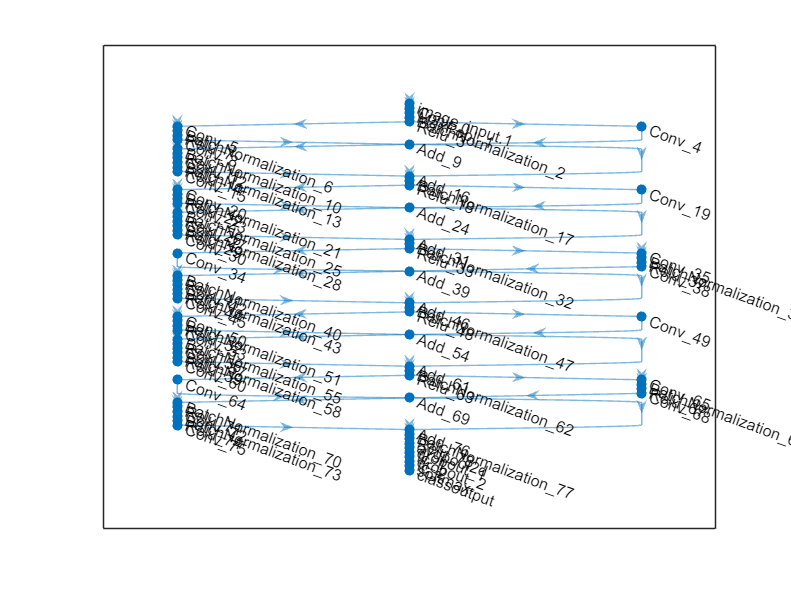

plot(lgraph);